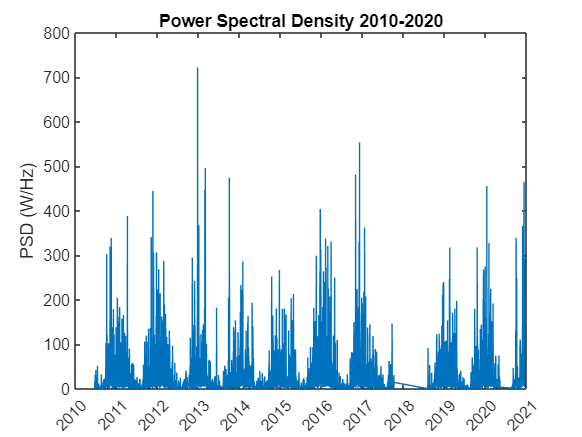

close all;
clear all;
t = ncread('http://thredds.cdip.ucsd.edu/thredds/dodsC/cdip/archive/166p1/166p1_historic.nc?waveTime[0:1:164282],wavePeakPSD[0:1:164282]','waveTime');
PSD = ncread('http://thredds.cdip.ucsd.edu/thredds/dodsC/cdip/archive/166p1/166p1_historic.nc?waveTime[0:1:164282],wavePeakPSD[0:1:164282]','wavePeakPSD');
Hs = ncread('http://thredds.cdip.ucsd.edu/thredds/dodsC/cdip/archive/166p1/166p1_historic.nc?waveTime[0:1:164282],waveHs[0:1:164282],wavePeakPSD[0:1:164282]','waveHs');

%all data - 10 years
[CDIPt,~,CDIPindices] = CDIPtime(t, Hs, 20100616160000, 20201215143000);
PSD_all = PSD(CDIPindices);
figure(1)
plot(CDIPt,PSD_all)
datetick
ylabel('PSD (W/Hz)')
title('Power Spectral Density 2010-2020')

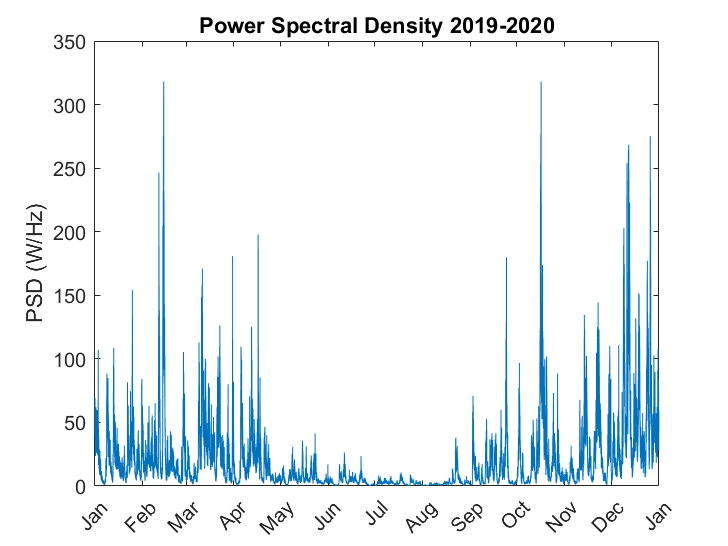

%1 year - 2019-2020
[CDIPt,~,CDIPindices] = CDIPtime(t, Hs, 20190101000000, 20200101000000);
PSD_yr = PSD(CDIPindices);
figure(2)
plot(CDIPt,PSD_yr)
datetick
ylabel('PSD (W/Hz)')
title('Power Spectral Density 2019-2020')

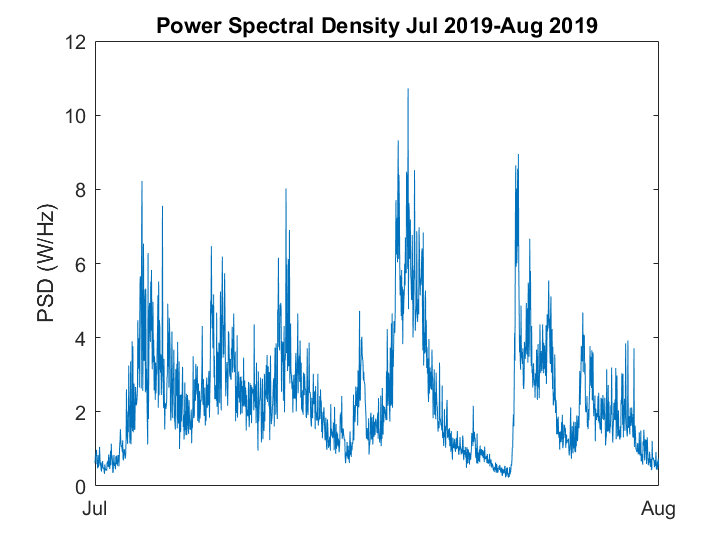

%1 month - july 2020
[CDIPt,~,CDIPindices] = CDIPtime(t, Hs, 20190701000000, 20190801000000);
PSD_mo = PSD(CDIPindices);
figure(3)
plot(CDIPt,PSD_mo)
datetick
ylabel('PSD (W/Hz)')
title('Power Spectral Density Jul 2019-Aug 2019')

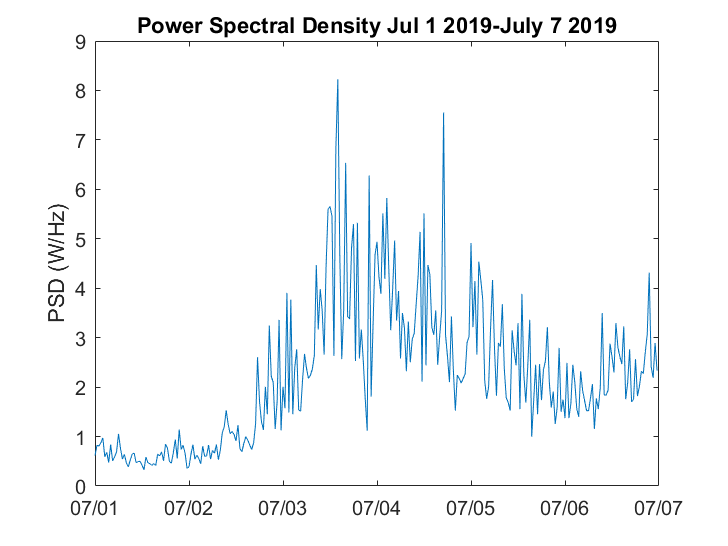

%1 week - july 2020
[CDIPt,CDIPHs,CDIPindices] = CDIPtime(t, Hs, 20190701000000, 20190707000000);
PSD_wk = PSD(CDIPindices);
figure(4)
plot(CDIPt,PSD_wk)
datetick
ylabel('PSD (W/Hz)')
title('Power Spectral Density Jul 1 2019-July 7 2019')